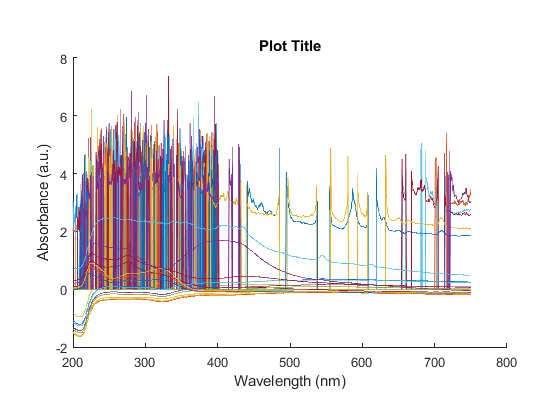

clc
clear

absorbtion_lower_wavelength = 200; %set the lower bound for the wavelength range you want to look at
absorbtion_upper_wavelength = 750; %set the upper bound for the wavelength range you want to look at

filepath = 'C:\Users\blhal\OneDrive - University of Leeds\Matlab\Code for Matt\Inline test folder'; %put the file path here, to the folder containing all the data files
myFiles = dir(fullfile(filepath)); %returns a struct containing the files containied in the directory and their properites, we can extract the number of files and file names from this

%newpath = strcat(filepath,'\processed\'); %creates a string that is used to make the 'processed' folder
%mkdir(newpath); %makes the processed folder

noOfFiles = (size(myFiles))-3; %returns the number of files in the directory
noOfFiles = noOfFiles(:,1); %removes the random '1' from the noOfFiles

times_array = zeros((noOfFiles),1); %preallocates a times array array to make computation faster
output_array = zeros((noOfFiles),1); %preallocates an output array to make computation faster

FileName = myFiles(3).name; %extracts the file name from the myFiles struct
fullFilePath = fullfile(filepath,FileName); %combines the file path with the file name
raw_data = dlmread(fullFilePath,'',14,0); %removes the first 14 lines of header text from the file and imports the wavelength and absorbtion data
wavelengths = raw_data(:,1); %imports the wavelegth data
wavelengths = wavelengths'; %concatenates the wavelength data
wavelengths = round(wavelengths); %rounds all of the wavelegths to the nearest integer
array_length = size(wavelengths); %counts the number of values in the wavelegth array
build_array = zeros((noOfFiles),array_length(1,2)); %preallocates a build array where the wavelength and absorbtion data will go to make computation faster
build_array(1,:) = wavelengths; %inserts the wavelengths into the prealocated build array

%this section gets the start time for the timeseries data
fileID = fopen(fullFilePath); %opens the first file
a = textscan(fileID,'%s','delimiter','\n','headerlines',2); %scans the first file contents ignoring the first 2 lines
file_scan = a{1}; %imports the scanned data
subArray = file_scan(1, 1); %extracts the first line of the scanned data (the date-time)
start_time = cell2mat(subArray); %converts the time from a cell array to an array
start_time_cut = strtrim(start_time(18:25)); %cuts the date out of the date-time array
start_time = datetime(start_time_cut,'InputFormat','HH:mm:ss'); %converts the string into a datetime data type
fclose(fileID); %closes the file so it can be opened again later

for i = 3:noOfFiles+2 %loops round until all the files have been processed ignores the two extra random .. and . files
    
    FileName = myFiles(i).name; %extracts the file name from the myFiles struct
    fullFilePath = fullfile(filepath,FileName); %combines the file path with the file name
    raw_data = dlmread(fullFilePath,'',14,0); %reads the wavelength and absorbtion data from each file into the loop
    
    absobtion = raw_data(:,2); %cuts out the absorbtion data 
    absobtion = absobtion'; %concatenates the absorbtion array 
    build_array(i-1,:) = absobtion; %builds an array of absobtion data
    
    indexwavelength = find(wavelengths==absorbtion_lower_wavelength); %finds the position in the array corrosponding to the set upper wavelenght limit
    averagewavelength = mean(indexwavelength); %takes the average position of the upper wavelenght limit
    absorbtion_lower_index = round(averagewavelength); %round this to get the best position
    
    indexwavelength = find(wavelengths==absorbtion_upper_wavelength); %finds the position in the array corrosponding to the set upper wavelenght limit
    averagewavelength = mean(indexwavelength); %takes the average position of the upper wavelenght limit
    absorbtion_upper_index = round(averagewavelength); %round this to get the best position
    
    wavelenghts_cut = round(wavelengths(1,absorbtion_lower_index:absorbtion_upper_index)); %cuts out the wavelenghts from the set bound limits
    absorb_cut = absobtion(1:end,absorbtion_lower_index:absorbtion_upper_index); %cuts out the absobtion values from the set bound limits
    

    
    %**************USER edit area*******************
    
    %here you create an output from the absorbtion data, e.g. max width
    %half length or lamda max, here I've just taken the mean of the cropped
    %absobtion data
    
    
    
    
    %put your own code here to generate time series data
    
    
    
    
    
    build_array_cut(i-1,:) = absorb_cut; %the mean average of all the scans taken during the run
    
    %**************end of USER edit area************
   
    
    %this section gets the times out of the txt files
    fileID = fopen(fullFilePath); %opens the file currently being looked at
    a = textscan(fileID,'%s','delimiter','\n','headerlines',2); %scans the textfile ignoring the first 2 lines
    file_scan = a{1}; %imports the scanned data
    subArray = file_scan(1, 1); %extracts the first line of the scanned data (the date-time)
    extract_time = cell2mat(subArray); %converts the time from a cell array to an array
    cut_out_time = strtrim(extract_time(18:25)); %cuts the date out of the date-time array
    fclose(fileID); %closes the file so it can be opened again later
    
    date_time = datetime(cut_out_time,'InputFormat','HH:mm:ss'); %convters the datetime string to a datetime data type
    date_time = date_time-start_time; %subtracts the start time from the current time to get absolute time 
    
    Duration_in_hours = hours(date_time); %converts absolute time to time in hours
    Duration_in_minutes = minutes(date_time); %converts absolute time to time in minutes
    Duration_in_seconds = seconds(date_time); %converts absolute time to time in seconds
    
    time = Duration_in_seconds; %select the units of time you want to plot
    times_array(i-2,1) = time; %builds an array of times for the plot below
    
end

hold on

plot(wavelenghts_cut,build_array_cut)

xlabel('Wavelength (nm)');
ylabel('Absorbance (a.u.)');
title('Plot Title');
pbaspect([1.5 1 1]) %change the aspect ratio of your plot

hold off


% data_output = [times_array(:) output_array(:)];
% exportFilePath = strcat(newpath,'output.txt');
% csvwrite(exportFilePath,data_output);
